 E.T.S. Ingeniería Informática                                                                                               Grado en Ingeniería de la Salud

 Ampliación de Matemáticas                                                                                                                            Curso 2023/24

***Práctica 3***

Considere el siguiente problema de contorno en ecuaciones diferenciales ordinarias: 		


$$y''= Ky + P, \qquad x \in (0,L), \qquad y'(0)=\alpha, \quad y(L)=\beta,
$$


para $K>0\ldotp$ 

- Resuelva analíticamente este problema e implemente en Matlab la solución obtenida en una función que reciba como parámetros los valores $L, K, P, \alpha, \beta, M$ y devuelva como resultado $[xa,ya]$ donde $xa$ es una partición equiespaciada del intervalo $ [0,L]$ con $M$subintervalos e $ya$ es la solución exacta evaluada en $xa$.

## Explique aquí como resuelve el problema de forma analítica y escriba la función en Matlab correspondiente al final del fichero

Para obtener la solución analítica hace falta calcular la solución homogénea y una particular


$$y = y_{h} + y_{p}$$


Solución Homogénea


$$y_{h}'' - Ky_{h} = 0
\\
\lambda^2 - K = 0
\\
\lambda = \sqrt{K}
\\
y_h = C_{1}e^{x\sqrt{K}} + C_{2}e^{-x\sqrt{K}}
$$


Solución Particular


$$y_{p}= Ax^2 + Bx + C
\\
y_{p}'= 2Ax + B
\\
y_{p}''= 2A
\\
y_{p}'' - Ky_p = P
\\
2A - K(Ax^2+Bx+C)=P
\\
Si: K>0; A=0; B=0; C=-P/K
\\
y_p=-P/K 
\\
\\
y =  C_{1}e^{x\sqrt{K}} + C_{2}e^{-x\sqrt{K}} -P/K
\\
y' =  C_{1}\sqrt{K}e^{x\sqrt{K}} - C_{2}\sqrt{K}e^{-x\sqrt{K}}$$


Aplicando las condiciones iniciales

C=A\B

C=[C1; C2]

A=[sqrt(K), -sqrt(K); exp(sqrt(K)L), exp(-sqrt(K)L)]

B=[alpha; beta+P/K]

2. Plantee un método de diferencias finitas de segundo orden sobre una partición equiespaciada para resolver este problema e impleméntelo en una función Matlab que reciba como parámetros los mismos valores que la función del apartado anterior  y devuelva como resultado $[xd,yd]$ donde $xd$ es una partición equiespaciada del intervalo $ [0,L]$ con $M$subintervalos e $yd$ es la solución calculada con el método de diferencias finitas.

## Explique aquí como plantearía el método de diferencias finitas y escriba la función en Matlab correspondiente al final del fichero


$$x_m = m\Delta x\\
y_m \approx y(x_m); m = 0,1,...,M\\
\Delta x=L/M\\
\frac{y_{m+1}-2y_m+y_{m-1}}{\Delta x^2}=Ky_m+P; m=0,...,M-1\\
y_m'=\frac{y_{m+1}-y_{m-1}}{2\Delta x}\\
y_{-1}=y_1-2\Delta x y_0' = y_1-2\alpha\Delta x \\
y_{m+1}-(2+K\Delta x^2)y_m+y_{m-1}=P\Delta x^2\\
m=0; 2y_{1}-(2+K\Delta x^2)y_0=P\Delta x^2+2\alpha\Delta x\\
m=M-1; -(2+K\Delta x^2)y_{M-1}+y_{M-2}=P\Delta x^2 - \beta
\\\\
AY=B; m=0,1,...,M-1

$$


3.  Plantee un método de elementos finitos basado en funciones continuas lineales a trozos sobre una partición equiespaciada para resolver este problema e impleméntelo en una función Matlab que reciba como parámetros los mismos valores que la función del apartado anterior  y devuelva como resultado $[xe,ye]$ donde $xe$ es una partición equiespaciada del intervalo $ [0,L]$ con $M$subintervalos e $ye$ es la solución calculada con el método de diferencias finitas.

## Explique aquí como plantearía el método de elementos finitos y escriba la función en Matlab correspondiente al final del fichero

Planteamos el problema, vamos a hacer uso de la siguiente función


$$\phi_m(x)=\left\lbrace\begin{array}{c} \frac{x-x_{m-1}}{\Delta x}; ~x\in[x_{m-1},x_m]\\ 
\frac{x-x_{m+1}}{-\Delta x}; ~x\in[x_{m},x_{m+1}]\\0~resto \end{array}\\
\phi_0(x)=\left\lbrace\begin{array}{c} \frac{x-x_{1}}{-\Delta x}; ~x\in[x_{0},x_1]\\0~resto \end{array}\\
$$


Formulación Débil


$$\int_{0}^L{y''(x)v(x)dx}=\int_{0}^L{(Ky(x)+P)v(x)dx}\\
[y'(x)v(x)]_0^L-\int_{0}^L{y'(x)v'(x)dx}=\int_{0}^L{(Ky(x)+P)v(x)dx}\\
y'(0)v(0)=\alpha v(x)\\
y'(L)v(L)=0; v(L)=0$$



$$Hallar ~y(x)=\sum_{m=0}^{M}{y_m\phi_m(x)}=\sum_{m=0}^{M-1}{y_m\phi_m(x)}+\beta\phi_M(x)\\
tal~que~j=0,1,...,M-1\\
-\alpha\phi_j(0)-\int_{0}^L{\sum_{m=0}^{M-1}{(y_m\phi'_m(x)}+\beta\phi'_M(x))\phi'_j(x)dx}=\\
=\int_{0}^L{[K(\sum_{m=0}^{M-1}{y_m\phi_m(x)}+\beta\phi_M(x))+P]\phi_j(x)dx}\\
a_{jm}=\int_{0}^L{[\phi'_m(x)\phi'_j(x)+K\phi_m(x)\phi_j(x)]dx}\\
b_j=\alpha\phi_j(0)+\int_{0}^L{[\beta\phi'_M(x)\phi'_j(x)}+K\beta\phi_M(x)\phi_j(x)+P\phi_j(x)]dx$$


4.  Utilice estas funciones para resolver los problemas propuestos con  $L=\;10,K=2,\;P=-1,\alpha =-1,\beta =1,M=10,100,1000$, compare la solución analítica con las obtenidas utilizando los métodos numéricos y comente los resultados obtenidos.

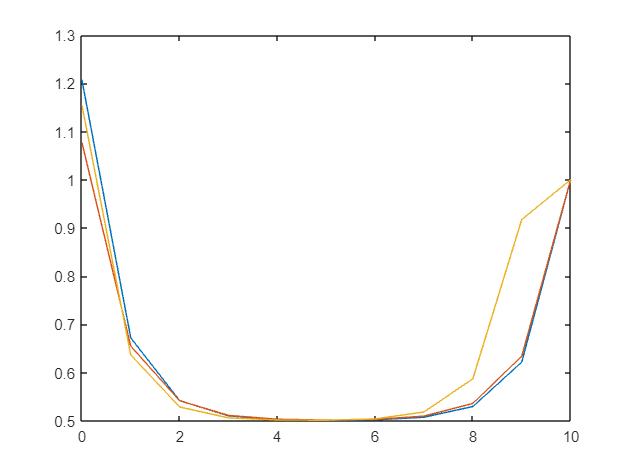

% Vamos a resolver el problema general: y''=K y+P, y'(0)=alp, y(L)=bet
% Tomando los siguientes valores para L,K,alp y bet:
figure
L=10;
K=2;
P=-1;
alp=-1;
bet=1;
% Las funciones exacta, DF y EF se deben implementar al final del fichero
% Hasta que no se implementen las funciones este código no va a funcionar
% A continuación se incluye un ejemplo de llamada para M=10 representado las soluciones obtenidas en una figura
[xex,yex]=exacta(L,K,P,alp,bet,10);
plot(xex,yex);
[xdf,ydf]=DF(L,K,P,alp,bet,10);
hold on;
plot(xdf,ydf)
[xef,yef]=EF(L,K,P,alp,bet,10);
plot(xef,yef)

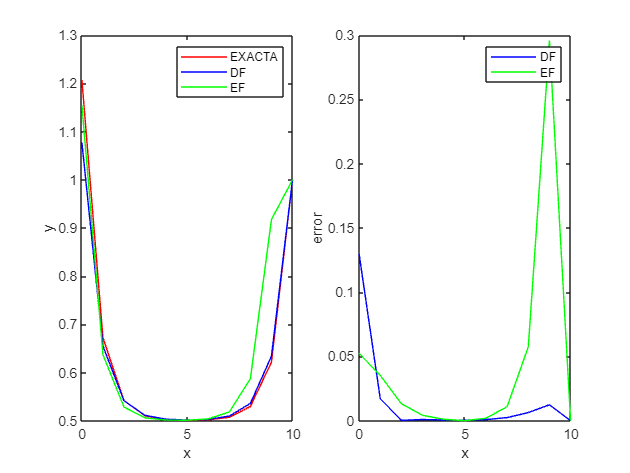

% Esta otra opción representa gráficamente las soluciones a la izquierda y los errores cometidos a la derecha
figure;% Para no continuar las gráficas en la figura generada anteriormente
subplot(121);
plot(xex,yex,'r',xdf,ydf,'b',xef,yef,'g');
legend('EXACTA','DF','EF')
xlabel('x');
ylabel('y');
subplot(122);
plot(xdf,abs(ydf'-yex),'b',xef,abs(yef-yex),'g');
legend('DF','EF')
xlabel('x');
ylabel('error');

%figure % Para no continuar las gráficas en la figura anterior
%clear xdf ydf xef yef yex; % Para que no haya problemas con los valores antiguos
% % INCLUYA AQUÍ EL CÓDIGO PARA M=100 Y 1000 Y COMENTE LOS RESULTADOS

***Nota 1***: Si tiene tiempo puede resolver este problema para otros valores de $L, K, P, \alpha, \beta$ y comentar los resultados que obtiene.

***Nota 2***: En el enunciado de la práctica se ha considerado $K>0$. ¿Es necesaria esta suposición? ¿Cómo cambiaría la forma de resolver el problema si no se hubiera hecho esta hipótesis? 

En la solución analítica, si K = 0, la solución particular se tendría que haber obtenido por algún otro método, ya que las constantes A, B y C propuestas no se habrían podido determinar.

APARTADO 1: SOLUCIÓN ANALÍTICA

function [xa,ya]=exacta(L,K,P,alp,bet,M)
% Solución analítica de y''=Ky+P, y'(0)=alp, y(L)=bet
% INCLUYA AQUÍ EL CÓDIGO CORRESPONDIENTE 
ax=L/M;
xa=0:ax:L;
A=[sqrt(K), -sqrt(K); exp(sqrt(K)*L), exp(-sqrt(K)*L)];
B=[alp; bet+P/K];
C=A\B;
ya=C(1).*exp(sqrt(K)*xa)+C(2).*exp(-sqrt(K)*xa)-P/K;
end


APARTADO 2: MÉTODO DE DIFERENCIAS FINITAS


function [xd,yd]=DF(L,K,P,alp,bet,M)
% Solución con diferencias finitas y''=K y+P, y'(0)=alp, y(L)=bet
% INCLUYA AQUÍ EL CÓDIGO CORRESPONDIENTE
ax=L/M;
xd=0:ax:L;
yd=zeros(M+1,1);
yd(M+1)=bet;
a=-(2+K*(ax)^2);
A=diag(a*ones(M,1))+(diag(ones(M-1,1),1))+(diag(ones(M-1,1),-1));
A(1,2)=2;
B=P*(ax)^2*ones(M,1);
B(1)=B(1)+2*alp*ax;
B(M)=B(M)-bet;
yd(1:M)=A\B;
end


APARTADO 3: MÉTODO DE ELEMENTOS FINITOS

function [xe,ye]=EF(L,K,P,alp,bet,M)
% Solución con elementos finitos y''=Ky+P, y'(0)=alp, y(L)=bet
% 
ax=L/M; % Necesito el valor de ax para definir variables con las integrales vistas en las transparencias
% Valor de la integral de phi_m^2 para n=1,...,m-1 (para m=0,M la mitad)
alp0=2*ax/3;
%  Valor de la integral de phi_m·phi_(m+1) =
%  = Valor de la integral de phi_m·phi_(m-1)
alp1= ax/6;
% Valor de la integral de phi_m'·phi_(m+1)' = 
% = Valor de la integral de phi_m'·phi_(m-1)';
bet1=-1/ax;
% Valor de la integral de phi_m'^2 para m=1...M-1 (para m=0,M la mitad)
bet0=2/ax;
% COMPLETE EL CÓDIGO 
ax=L/M;
xe=0:ax:L;
ye=zeros(1,M+1);
ye(M+1)=bet;
a=-K*alp0-bet0;
b=-K*alp1-bet1;
A=a*eye(M)+b*diag(ones(M-1,1),1)+b*diag(ones(M-1,1),-1);
A(1,1)=A(1,1)/2;
delt=ax;
B=P*delt*ones(M,1);
B(1)=B(1)/2+alp;
B(M)=B(M)+bet*a/2;
ye(1:M)=A\B;
end
